# **ASL American Sign Language Detection using Bayesian Networks and Convolutional Neural Networks**

## Course “Advanced Data Analysis and Machine Learning”

### **Project work 2**

### Authors: 

#### Thanh Tran (000285359)

#### Nghia Nguyen (000275466)

#### Swapnil Baad (000323486)

Report can be accessed with read-only priviledge from [Group_ASL_A2_report.docx](https://lut-my.sharepoint.com/:w:/g/personal/thanh_tran_student_lut_fi/ERNxVSaZ6XhNpJh_Ecmp26oBOtcaGtWC5TtH-ybKX2-_Uw?e=hczf4M)

## SETUP

% Add path to BNT toolbox
path_to_BNT = "C:\Users\thanh\bnt";
addpath(genpath(path_to_BNT));

% Add services folder containing helper functions
addpath('./services');
% Add extracted data folder
addpath('./extracted_features');

temp = false;
Training_data_loading = true;
Testing_data_loading = false;
Feature_extraction_1_example = false;
Feature_extraction_1_actual = false;    % This step takes 5hours
Feature_extraction_2_example = false;
Feature_extraction_2_actual = false;    % This step takes even more. Therefore, extracted data has been saved for later use.
Data_transformation = false;

## IMPORT DATA

### 1 Loading Training data

if Training_data_loading
    % Define environment variables
    class_list = ["K", "L", "M", "N", "O", "P", "Q", "R", "S", "T"];                                    % All classes included in this project
    class_list = sort(class_list);
    nClass = length(class_list);                                 % The number of classes included
    
    
    train_data_path = "./data/asl_alphabet_train/asl_alphabet_train";                                  % File path to the directory of train data
    
    % Load images and convert to RGB data matrices
    Xtemplates_filename = {};
    Ytemplates = [];
    Xtrain = {};
    Ytrain = [];
    nTrainSamplePerClass = zeros(nClass, 1);
    disp("Training data loading ...");

    for c = 1:nClass    
        class_dir = sprintf(train_data_path + "/" + class_list(c));
        file_list = dir(class_dir);
        file_list = file_list(3:end);
        nImage = length(file_list);
        nTrainSamplePerClass(c) = nImage;
        for i = 1:nImage
            path_to_image = sprintf(class_dir + "/" + file_list(i).name);
            image_RGB = imread(path_to_image);
            image_gray = rgb2gray(image_RGB);
            Xtrain{end+1} = image_gray;
            Ytrain = [Ytrain; class_list(c)];
            
            % Get one every 100 images per class and save as templates of class
%             if ismember(i, 1:100:nImage)
%                 Xtemplates_filename{end+1} = path_to_image;
%                 Ytemplates = [Ytemplates, class_list(c)];
%             end
    
        end
    
        fprintf('   Class %s loading done.\n', class_list(c));
    end

%     save extracted_features\templates.mat Xtemplates_filename Ytemplates
    
%     save extracted_features\Ytrain.mat Ytrain

    nXtrain = length(Xtrain);
    Cum_nTrainSamplePerClass = cumsum(nTrainSamplePerClass);
end

Training data loading ...


   Class K loading done.
   Class L loading done.
   Class M loading done.
   Class N loading done.
   Class O loading done.
   Class P loading done.
   Class Q loading done.


### 2 Loading testing data

if Testing_data_loading
    test_data_path = "./data/asl_alphabet_test/asl_alphabet_test";                                     % File path to the directory of test data
    Xtest = {};
    Ytest = [];
    nTestSamplePerClass = zeros(nClass, 1);
    disp('Testing data loading ...');
    
    file_list = dir(test_data_path);
    file_list = file_list(3:end);
    regex_class = sprintf('%s-%s', class_list(1), class_list(end));
    regex_file_name = sprintf('^(?<file_name>[%s]_test.jpg)', regex_class);
    test_files_cell = regexpi({file_list.name}, regex_file_name, 'names','lineanchors');
    test_files = vertcat(test_files_cell{:})
    nXtest = length(test_files);
    
    for f = 1:nXtest
        file_name = test_files(f).file_name;
        
        path_to_image = sprintf(test_data_path + "/" + file_name);
        image_RGB = imread(path_to_image);
        image_gray = rgb2gray(image_RGB);
        Xtest{end+1} = image_gray;
        Ytest = [Ytest; file_name(1)];
    end
end

## FEATURE EXTRACTION

### 1 Hand segmentation and SIFT Feature Extraction

#### 1.1 Examples with visualization

if Feature_extraction_1_example && Training_data_loading
    nExample = 1;
    nExampleClass = 3;
    for c = 1:nExampleClass
        fprintf('Class %s feature extracting example(s):\n', class_list(c));
        sample_idxs = find(Ytrain == class_list(c), nExample);
        for i = 1:nExample
            SIFT_points = bound_key_region(Xtrain{sample_idxs(i)}, true);
        end
    end
end

#### 1.2 Actual Extraction

Xtrain_SIFTPoints_var_name = {'SP1x','SP1y','SP2x','SP2y','SP3x','SP3y','SP4x','SP4y','SP5x','SP5y'};

if Feature_extraction_1_actual && Training_data_loading
    nSIFTPoints = 5;
    Xtrain_SIFTPoints = zeros(nXtrain, nSIFTPoints*2);
    for i = 1:nXtrain
        SIFT_points = bound_key_region(Xtrain{i});
        Xtrain_SIFTPoints(i,1:length(SIFT_points)) = SIFT_points;
        if ismember(i, Cum_nTrainSamplePerClass)
            fprintf('   Class %s feature extracting done.\n', Ytrain(i));
        end
    end
    
%     save extracted_features\Xtrain_SIFTPoints.mat Xtrain_SIFTPoints
end

### 2 Matched SURF Feature counts

#### 2.1 Examples with visualization

if Feature_extraction_2_example && Training_data_loading
    nExample = 1;
    nExampleClass = 3;
    for c = 1:nExampleClass
        fprintf('Class %s feature extracting example(s):\n', class_list(c));
        sample_idxs = find(Ytrain == class_list(c), nExample);
        for i = 1:nExample
            bestnMatches = get_best_nMatchedFeatures(Xtrain{sample_idxs(i)}, true);
        end
    end
end

#### 2.2 Actual Extraction

Xtrain_nMatchedFeatures_var_name = {'MFK','MFL','MFM','MFN','MFO','MFP','MFQ','MFR','MFS','MFT'};

if Feature_extraction_2_actual && Training_data_loading
    load extracted_features\templates.mat Xtemplates_filename Ytemplates
    TemplateClasses = unique(Ytemplates);
    nTemplateClasses = length(TemplateClasses);

    Xtrain_nMatchedFeatures = zeros(nXtrain,nTemplateClasses);
    for i = 1:nXtrain
        Xtrain_nMatchedFeatures(i,:) = get_best_nMatchedFeatures(Xtrain{i}, false);
    end
    
%     save extracted_features\Xtrain_nMatchedFeatures.mat Xtrain_nMatchedFeatures
end

## EXTRACTED DATA TRANSFORMATION

if Data_transformation
    SIFT_FEATURES_FILE = ".\extracted_features\Xtrain_SIFTPoints.mat";
    Xtrain_SIFTPoints_var_name = {'SP1x','SP1y','SP2x','SP2y','SP3x','SP3y','SP4x','SP4y','SP5x','SP5y'};
    
    SUFTCOUNT_FEATURES_FILE = '.\extracted_features\Xtrain_nMatchedFeatures.mat';
    Xtrain_nMatchedFeatures_var_name = {'MFK','MFL','MFM','MFN','MFO','MFP','MFQ','MFR','MFS','MFT'};
    
    Xtrain_SIFTPoints_table = load_data_and_transform_to_table(SIFT_FEATURES_FILE, 'Xtrain_SIFTPoints', Xtrain_SIFTPoints_var_name, true);
    Xtrain_nMatchedFeatures_table = load_data_and_transform_to_table(SUFTCOUNT_FEATURES_FILE, 'Xtrain_nMatchedFeatures', Xtrain_nMatchedFeatures_var_name, false);
    
%     save extracted_features\Xtrain_SIFTPoints_table.mat Xtrain_SIFTPoints_table
%     save extracted_features\Xtrain_nMatchedFeatures_table.mat Xtrain_nMatchedFeatures_table
    
    Xtrain_extracted = [Xtrain_SIFTPoints_table Xtrain_nMatchedFeatures_table];
%     save extracted_features\Xtrain_extracted.mat Xtrain_extracted
end



## Bayesian Network

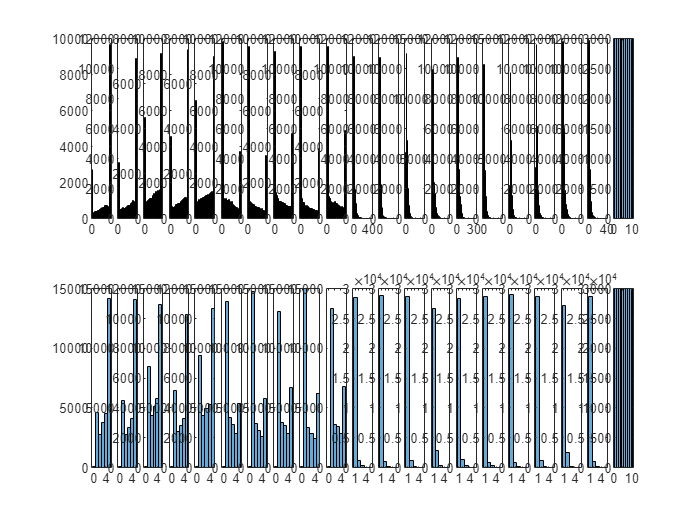

load extracted_features\Xtrain_extracted.mat Xtrain_extracted
load extracted_features\Ytrain.mat Ytrain

% USE VARIABLE NAMED Xtrain_extracted AS TRAINING AND VALIDATING DATA
[nXtrain, nCol] = size(Xtrain_extracted);
varLabels = ["SP1x", "SP1y", "SP2x", "SP2y", "SP3x", "SP3y", "SP4x", "SP4y", "SP5x", "SP5y","MFK","MFL","MFM","MFN","MFO","MFP","MFQ","MFR","MFS","MFT", "Label"];

% Discretization

nseg = 5;
X_train = table2array(Xtrain_extracted);
X_train(:,end+1) = grp2idx(categorical(Ytrain));

X_train_Descrt = zeros(size(X_train));

for i = 1:length(X_train(1,1:end-1))
    var     = X_train(:,i);

    minVal  = min(var);
    maxVar  = max(var);

    segLength = maxVar - minVal;
    subSegLength = segLength/nseg;

    seg(1).LB = minVal;

    for ii = 1:nseg
        if ii ~= 1
            seg(ii).LB = seg(ii-1).LB + subSegLength + 0.0001;
        end
    end

    for ii = 1:nseg-1
        idxCurrent = intersect(find(X_train(:,i)>=seg(ii).LB), find(X_train(:,i)<seg(ii+1).LB));
        X_train_Descrt(idxCurrent,i) = ii;
    end

    idxCurrent = find(X_train(:,i)>seg(ii+1).LB);
    X_train_Descrt(idxCurrent,i) = ii+1;
end

% Visualizing the data
X_train_Descrt(:,end) = X_train(:,end);

[row, col]      = size(X_train_Descrt);
[row2, col2]      = size(X_train);


ii = 1;
for i = 1:col
    subplot(2, col, i);
    histogram(X_train(:,i));

    subplot(2, col, i+col);
    histogram(X_train_Descrt(:,i));
end

% Partitioning
c       = cvpartition(X_train(:,end), 'Holdout', 0.3);
idxTest = test(c);
idxCal  = training(c);

% % For point 4.2, run the following  commented
% %code with your choice of removed variables
% data2(:, [2 3 4 5 6 7 9 10])  = [];
% varLabels([2 3 4 5 6 7 9 10]) = [];
% [row, col]             = size(data2);

dataAll  = X_train_Descrt;
X_train_Descrt    = [];
X_train_Descrt    = dataAll(idxCal,  :);
dataTest = dataAll(idxTest, :);


%% Modeling
folderPath = 'C:\Users\swapn\Downloads\bnt-master\bnt-master';
addpath(genpath(folderPath))

ncases  = row;
cases   = cell(col, ncases);
cases   = num2cell(X_train_Descrt');

node_sizes = [];
for i = 1:col
    node_sizes = [node_sizes, length(unique(X_train_Descrt(:,i)))];
    variable(i).node = i;
end

DAGhat = learn_struct_K2(cases, node_sizes, [variable.node], ...
    'max_fan_in', 3, 'verbose', 'yes');


node 1, empty score -29705.5777

node 2, empty score -29713.7635
considering adding 1 to 2, score -28070.9599
* adding 1 to 2, score -28070.9599

node 3, empty score -31794.6949
considering adding 1 to 3, score -31114.7555
considering adding 2 to 3, score -30862.4012
* adding 2 to 3, score -30862.4012
considering adding 1 to 3, score -30977.5492

node 4, empty score -30467.3497
considering adding 1 to 4, score -29481.8036
considering adding 2 to 4, score -29653.2084
considering adding 3 to 4, score -29540.1800
* adding 1 to 4, score -29481.8036
considering adding 2 to 4, score -29488.4046
considering adding 3 to 4, score -29321.9380
* adding 3 to 4, score -29321.9380
considering adding 2 to 4, score -31664.8795

node 5, empty score -31754.5469
considering adding 1 to 5, score -31381.7937
considering adding 2 to 5, score -31277.8557
considering adding 3 to 5, score -31436.5226
considering adding 4 to 5, score -30933.5784
* adding 4 to 5, score -30933.5784
considering adding 1 to 5, sco

## Bayesian Network Structure

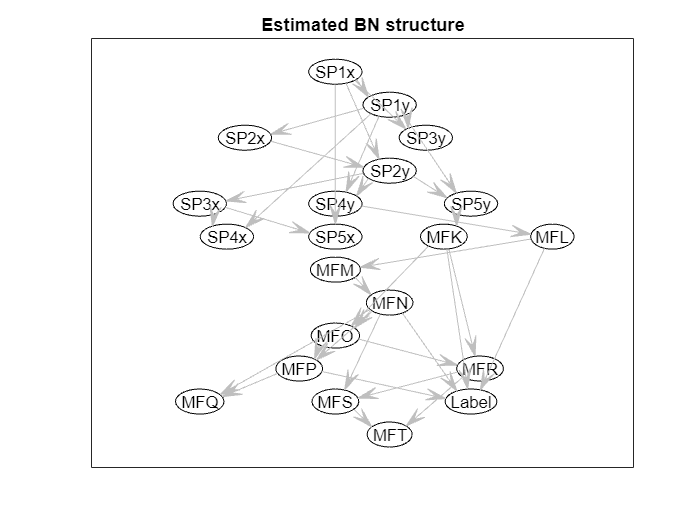

BNtemp = mk_bnet(DAGhat, node_sizes);

for i = 1:col
    BNtemp.CPD{variable(i).node} = tabular_CPD(BNtemp, variable(i).node);
end

BNhat = learn_params(BNtemp, cases);

CPThat = cell(1, col);
for i = 1:col
    s = struct(BNhat.CPD{i});
    CPThat{i} = s.CPT;
end


figure;
draw_graph(BNhat.dag, varLabels);
title('Estimated BN structure');


%Classification
engine       = global_joint_inf_engine(BNhat);
[rowT, colT] = size(dataTest);


for j = 1:rowT
    evidence     = [];
    evidence     = cell(1,colT);
    
    for i = 1:col-1
       evidence{variable(i).node} = dataTest(j,i);
    end
    
    [engine, logLikelihood] = enter_evidence(engine, evidence);
    marginal       = marginal_nodes(engine, variable(end).node);
    totProb        = sum(marginal.T(:));
    dataPoint(j).M = marginal.T ./ totProb;
    [~, dataPoint(j).yhat] = max(dataPoint(j).M);
end

Array indices must be positive integers or logical values.

Error in discrete_CPD/convert_to_table (line 14)
T = CPT(index{:});

Error in discrete_CPD/convert_to_pot (line 20)
   T = convert_to_table(CPD, domain, evidence);

Error in <a href="matlab:matlab.internal.language.introspective.errorDocCallback('compute_joint_pot', 'C:\Users\thanh\bnt\BNT\general\compute_joint_pot.m', 14)" style="fon


a = categorical([dataPoint.yhat]');
b = categorical(dataTest(:,end));

p1 = find(a == b, 1, 'first');
p2 = find(a ~= b, 1, 'first');

## TESTING

Function "sign_language_detect.m" can be used to make prediction either from loaded grayscale image data matrix or from a path-to-image. "Visual" flags can be used to allow visualization and plotting.

% example
file_name = test_files(1).file_name
path_to_image = sprintf(test_data_path + "/" + file_name);
Ypred = sign_language_detect(path_to_image, true);